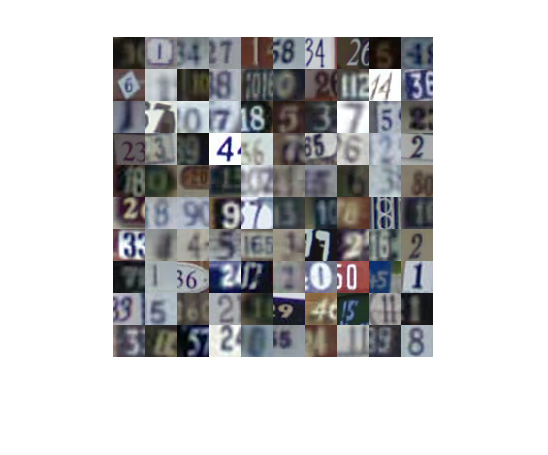

load('q3_train.mat');
train = reshape(train_X, [32, 32, 3, length(train_X)]);
train_y = categorical(train_Y);
load('q3_test.mat');
test = reshape(test_X, [32, 32, 3, length(test_X)]);
test_y = categorical(test_Y);
imshow(imtile(train(:,:,:,1:100)))

**Best Model**

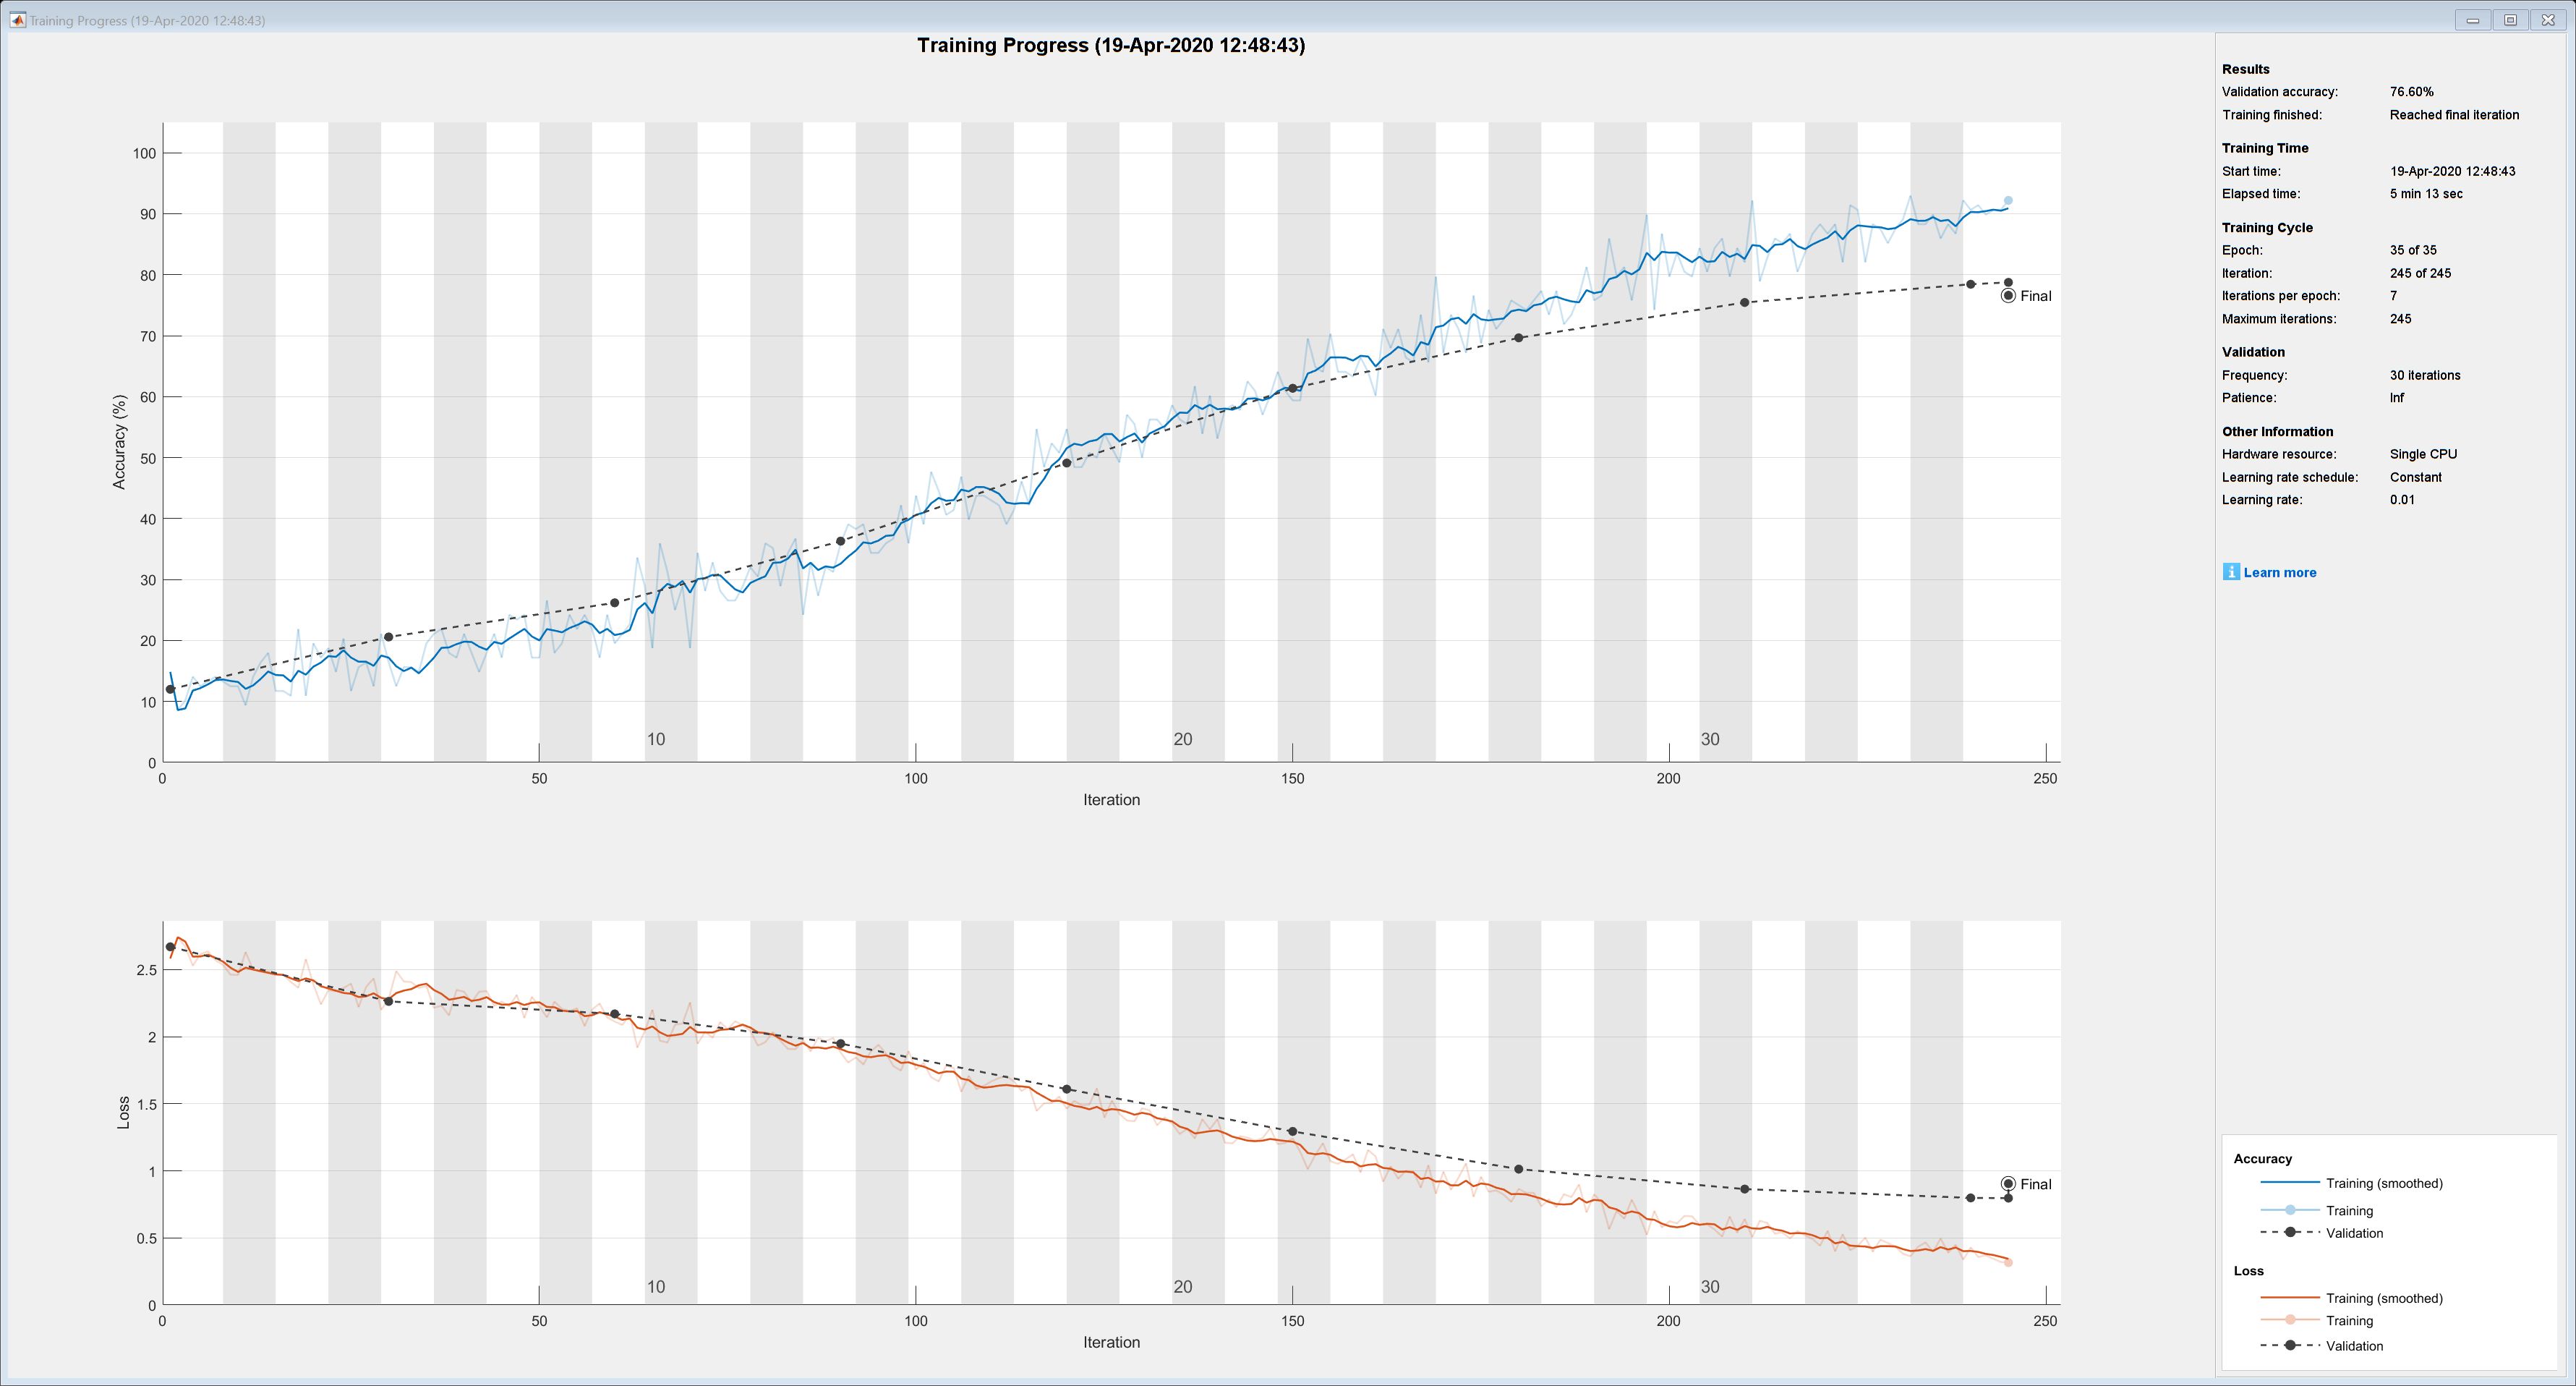

layers = [
    imageInputLayer([32 32 3])
    
    convolution2dLayer(3,32,'Padding','same')
    leakyReluLayer
    convolution2dLayer(3,32,'Padding','same')
    dropoutLayer(0.2)
    batchNormalizationLayer
    leakyReluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,64,'Padding','same')
    leakyReluLayer
    convolution2dLayer(3,64,'Padding','same')
    dropoutLayer(0.2)
    batchNormalizationLayer
    leakyReluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,128,'Padding','same')
    leakyReluLayer
    convolution2dLayer(3,128,'Padding','same')
    dropoutLayer(0.2)
    batchNormalizationLayer
    leakyReluLayer
    
    fullyConnectedLayer(1024)
    dropoutLayer(0.5)
    batchNormalizationLayer
    leakyReluLayer
    
    fullyConnectedLayer(256)
    dropoutLayer(0.5)
    batchNormalizationLayer
    leakyReluLayer

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',35, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{test, test_y}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(train, train_y, layers, options);

**Simple Model**

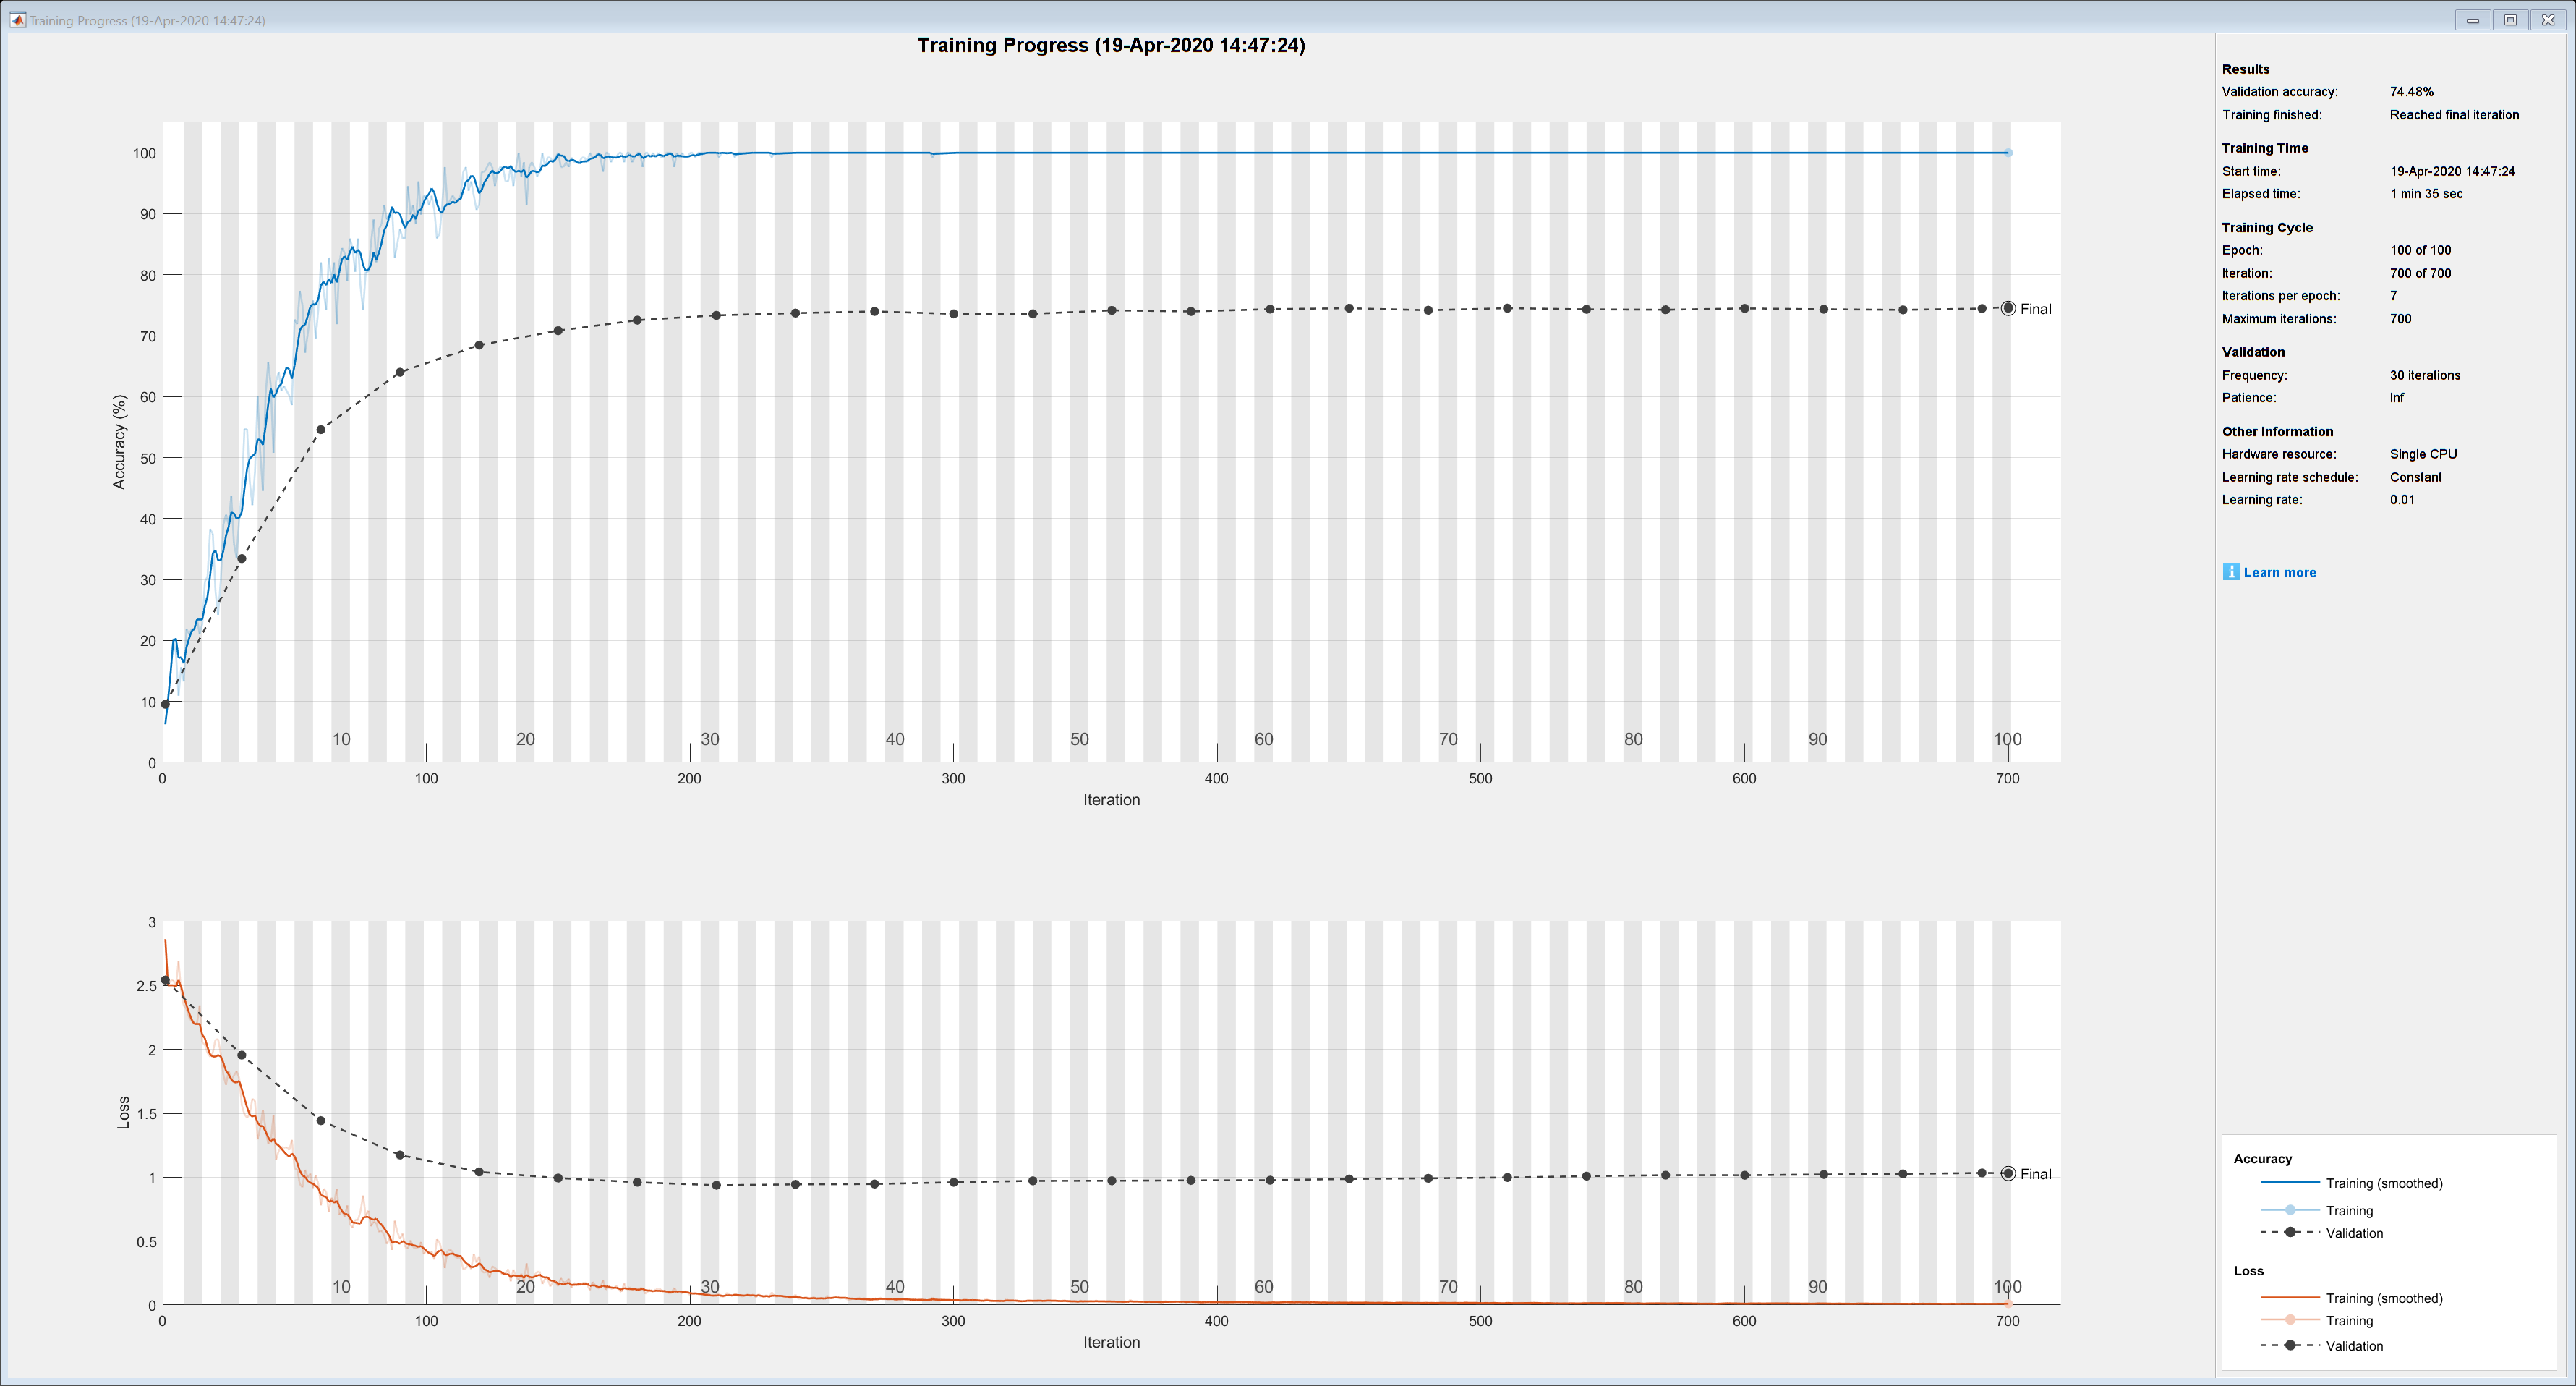

layers = [
    imageInputLayer([32 32 3])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',100, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{test, test_y}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(train, train_y, layers, options);

**Overfitted model**

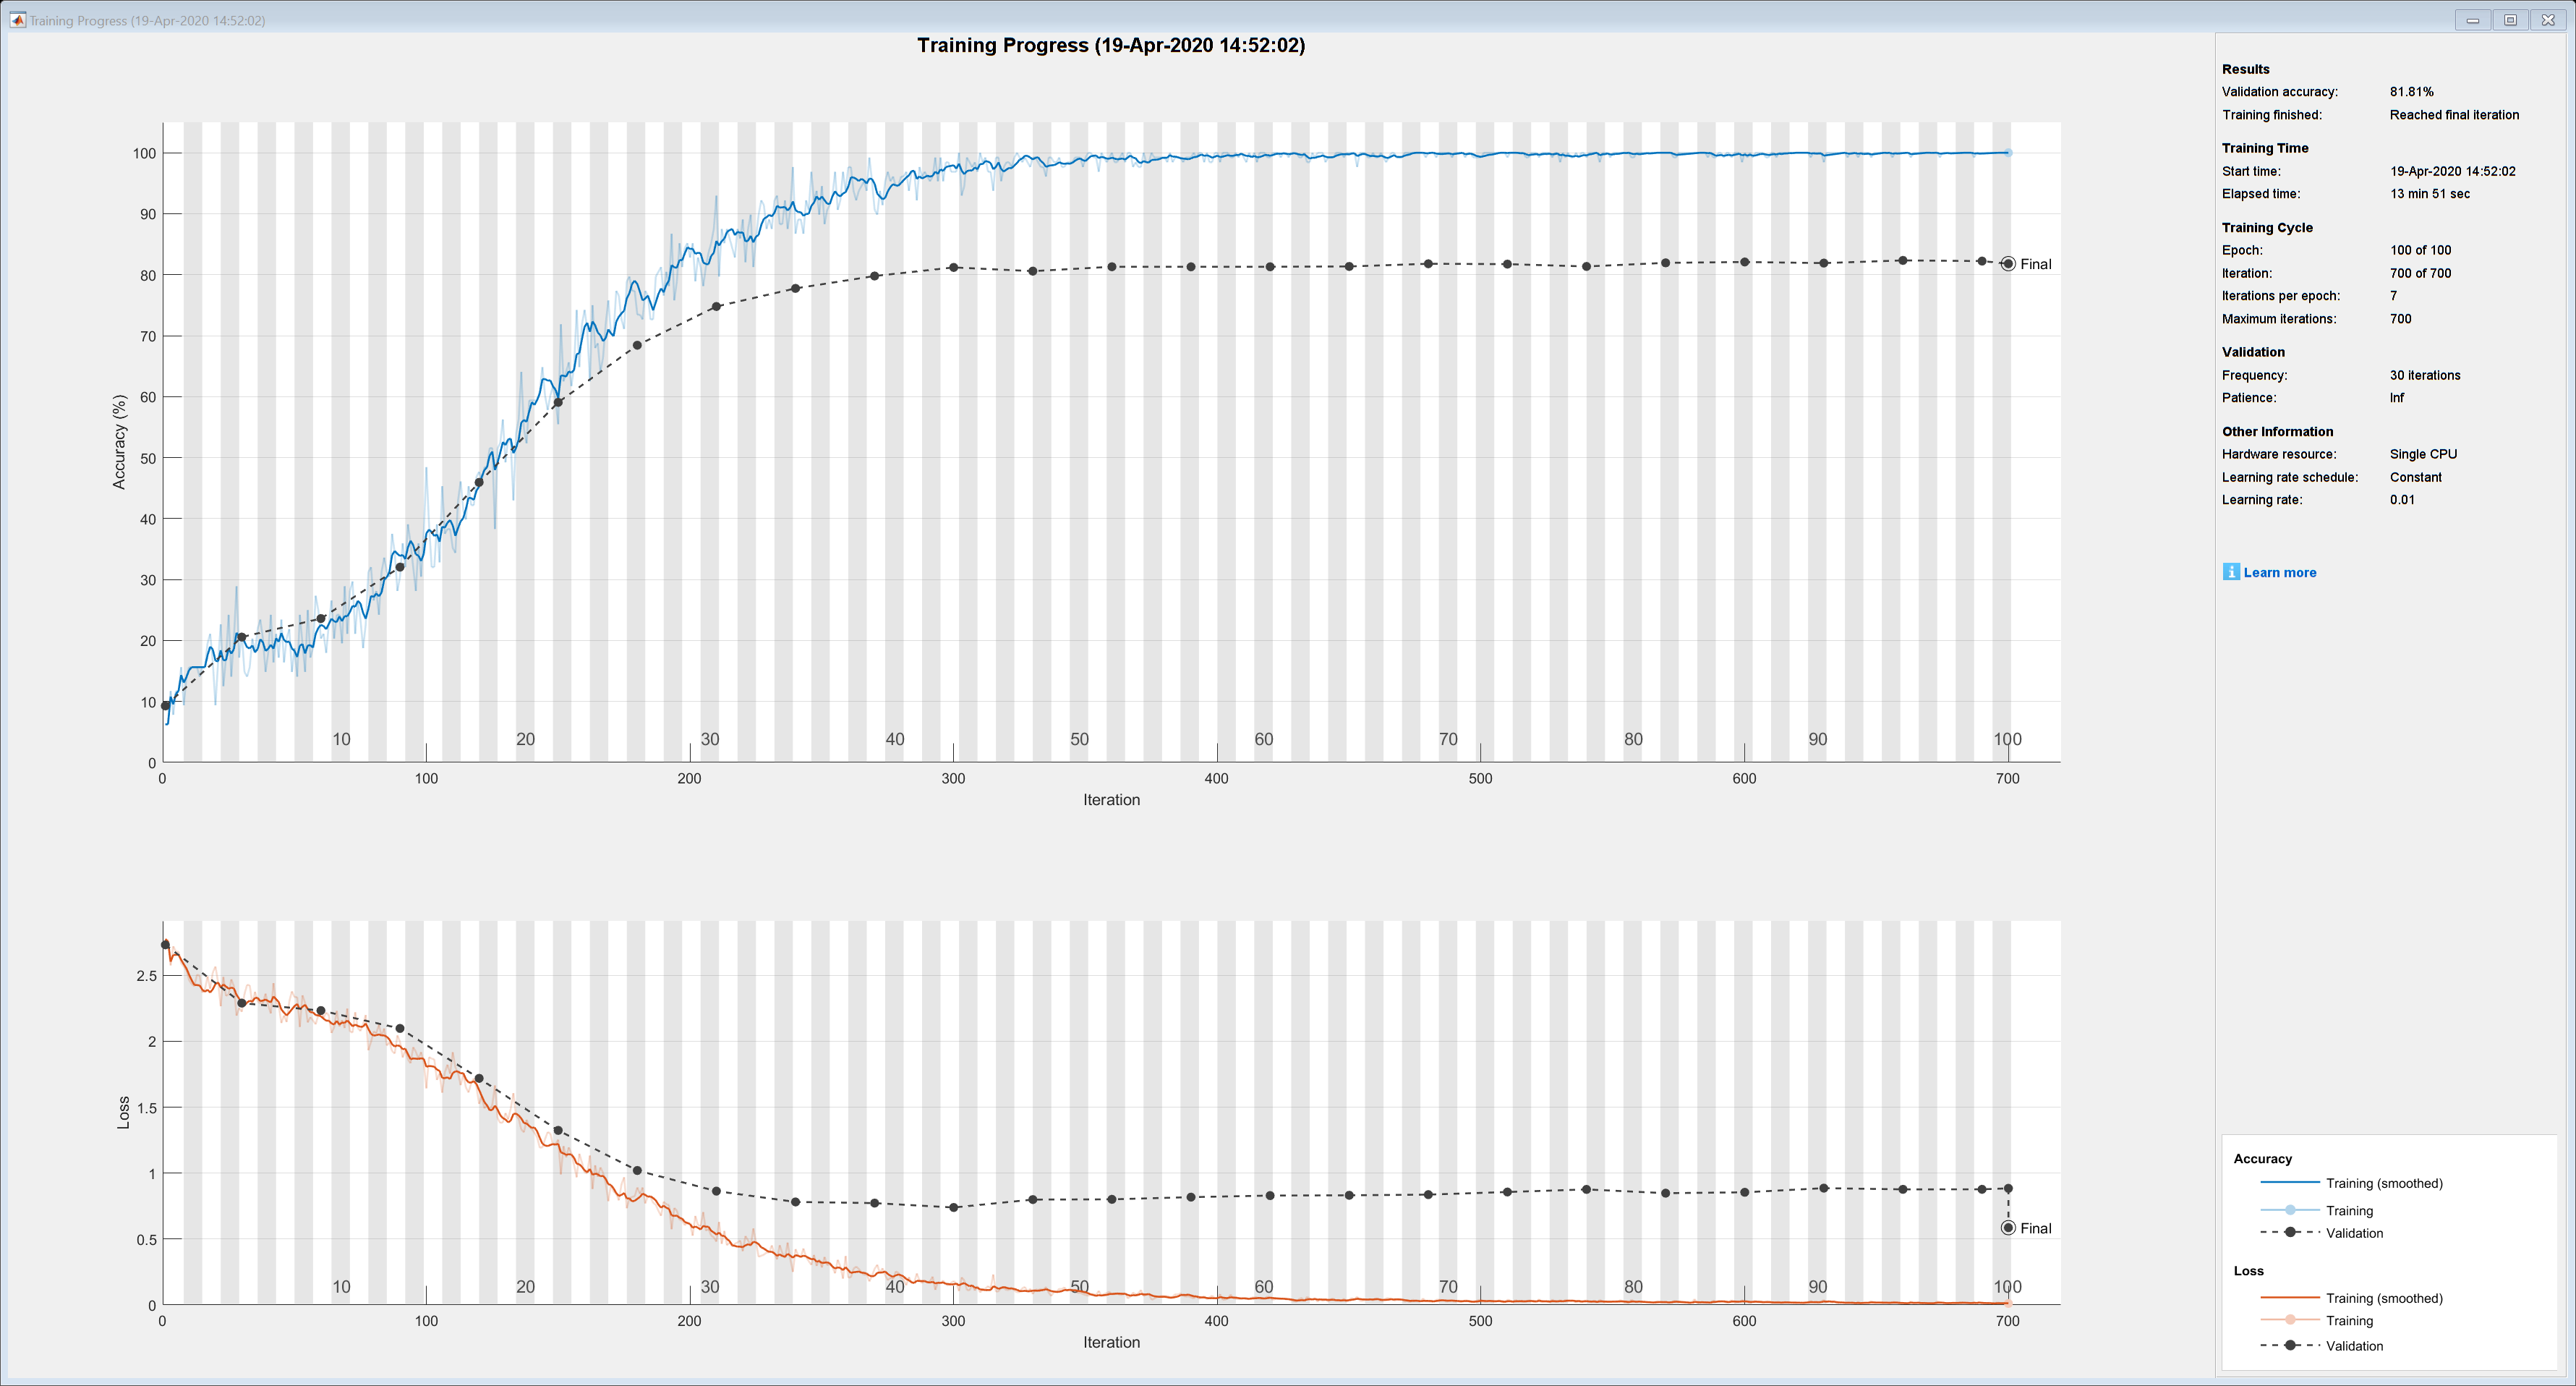

layers = [
    imageInputLayer([32 32 3])
    
    convolution2dLayer(3,32,'Padding','same')
    leakyReluLayer
    convolution2dLayer(3,32,'Padding','same')
    dropoutLayer(0.2)
    batchNormalizationLayer
    leakyReluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,64,'Padding','same')
    leakyReluLayer
    convolution2dLayer(3,64,'Padding','same')
    dropoutLayer(0.2)
    batchNormalizationLayer
    leakyReluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,128,'Padding','same')
    leakyReluLayer
    convolution2dLayer(3,128,'Padding','same')
    dropoutLayer(0.2)
    batchNormalizationLayer
    leakyReluLayer
    
    fullyConnectedLayer(1024)
    dropoutLayer(0.5)
    batchNormalizationLayer
    leakyReluLayer
    
    fullyConnectedLayer(256)
    dropoutLayer(0.5)
    batchNormalizationLayer
    leakyReluLayer

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',100, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{test, test_y}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(train, train_y, layers, options);

**Data augmentation**

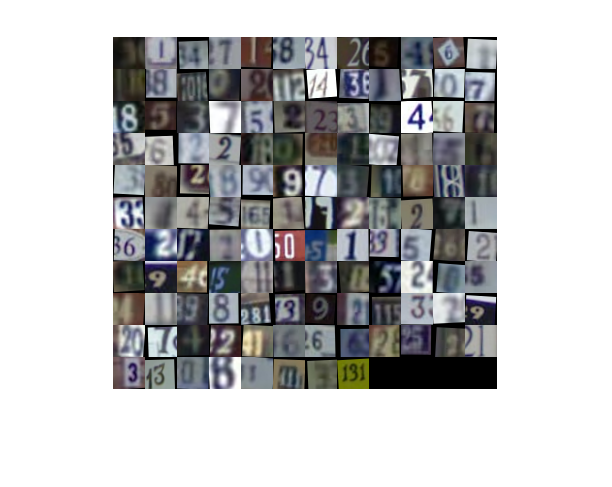

imageSize = [32 32];
pixelRange = [-3 3];
rotationRange = [-5 5];
scaleRange = [0.9 1.2];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',false, ...
    'RandScale', scaleRange, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...   
    'RandRotation', rotationRange);    
augimdsTrain = augmentedImageDatastore(imageSize, train, train_y, ...
    'DataAugmentation',imageAugmenter, ...
    'OutputSizeMode','randcrop');
sample = augimdsTrain.read;
preview_images = zeros(32,32,3,size(sample,1));
for i=1:size(sample,1)
    preview_images(:,:,:,i) = cell2mat(sample.input(i));
end
figure
imshow(imtile(preview_images/255))

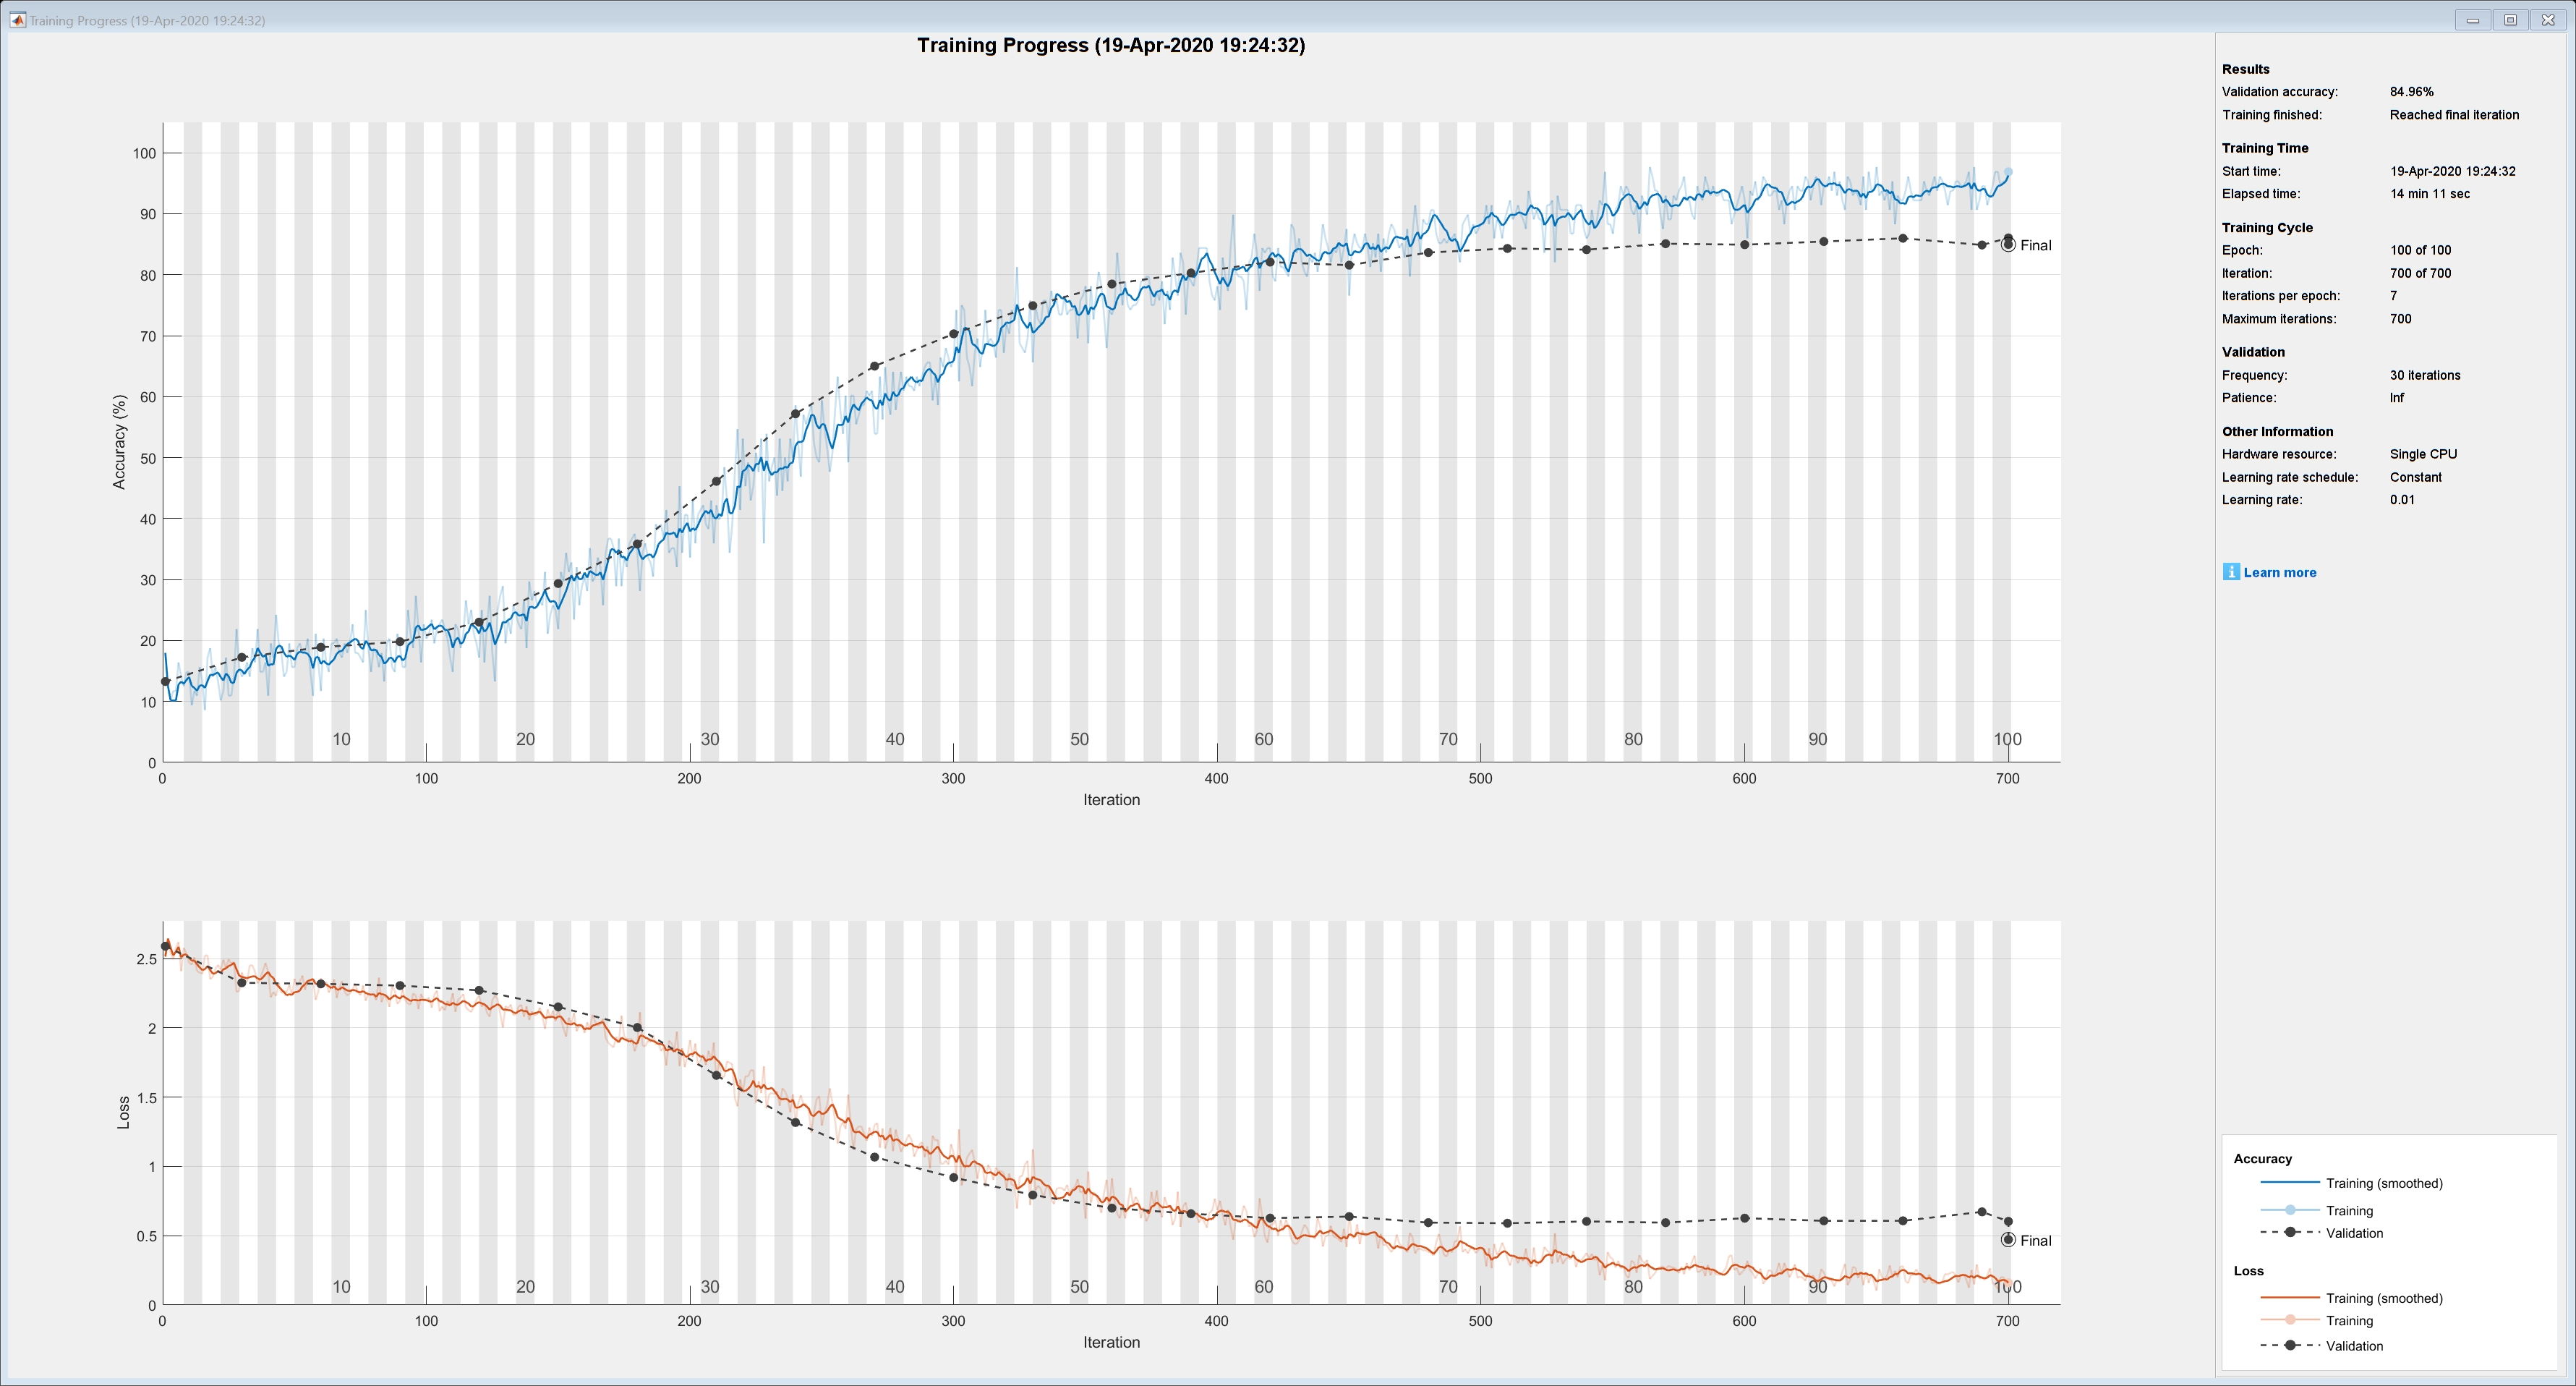

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',100, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{test, test_y}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
trainedNet = trainNetwork(augimdsTrain, layers, options);

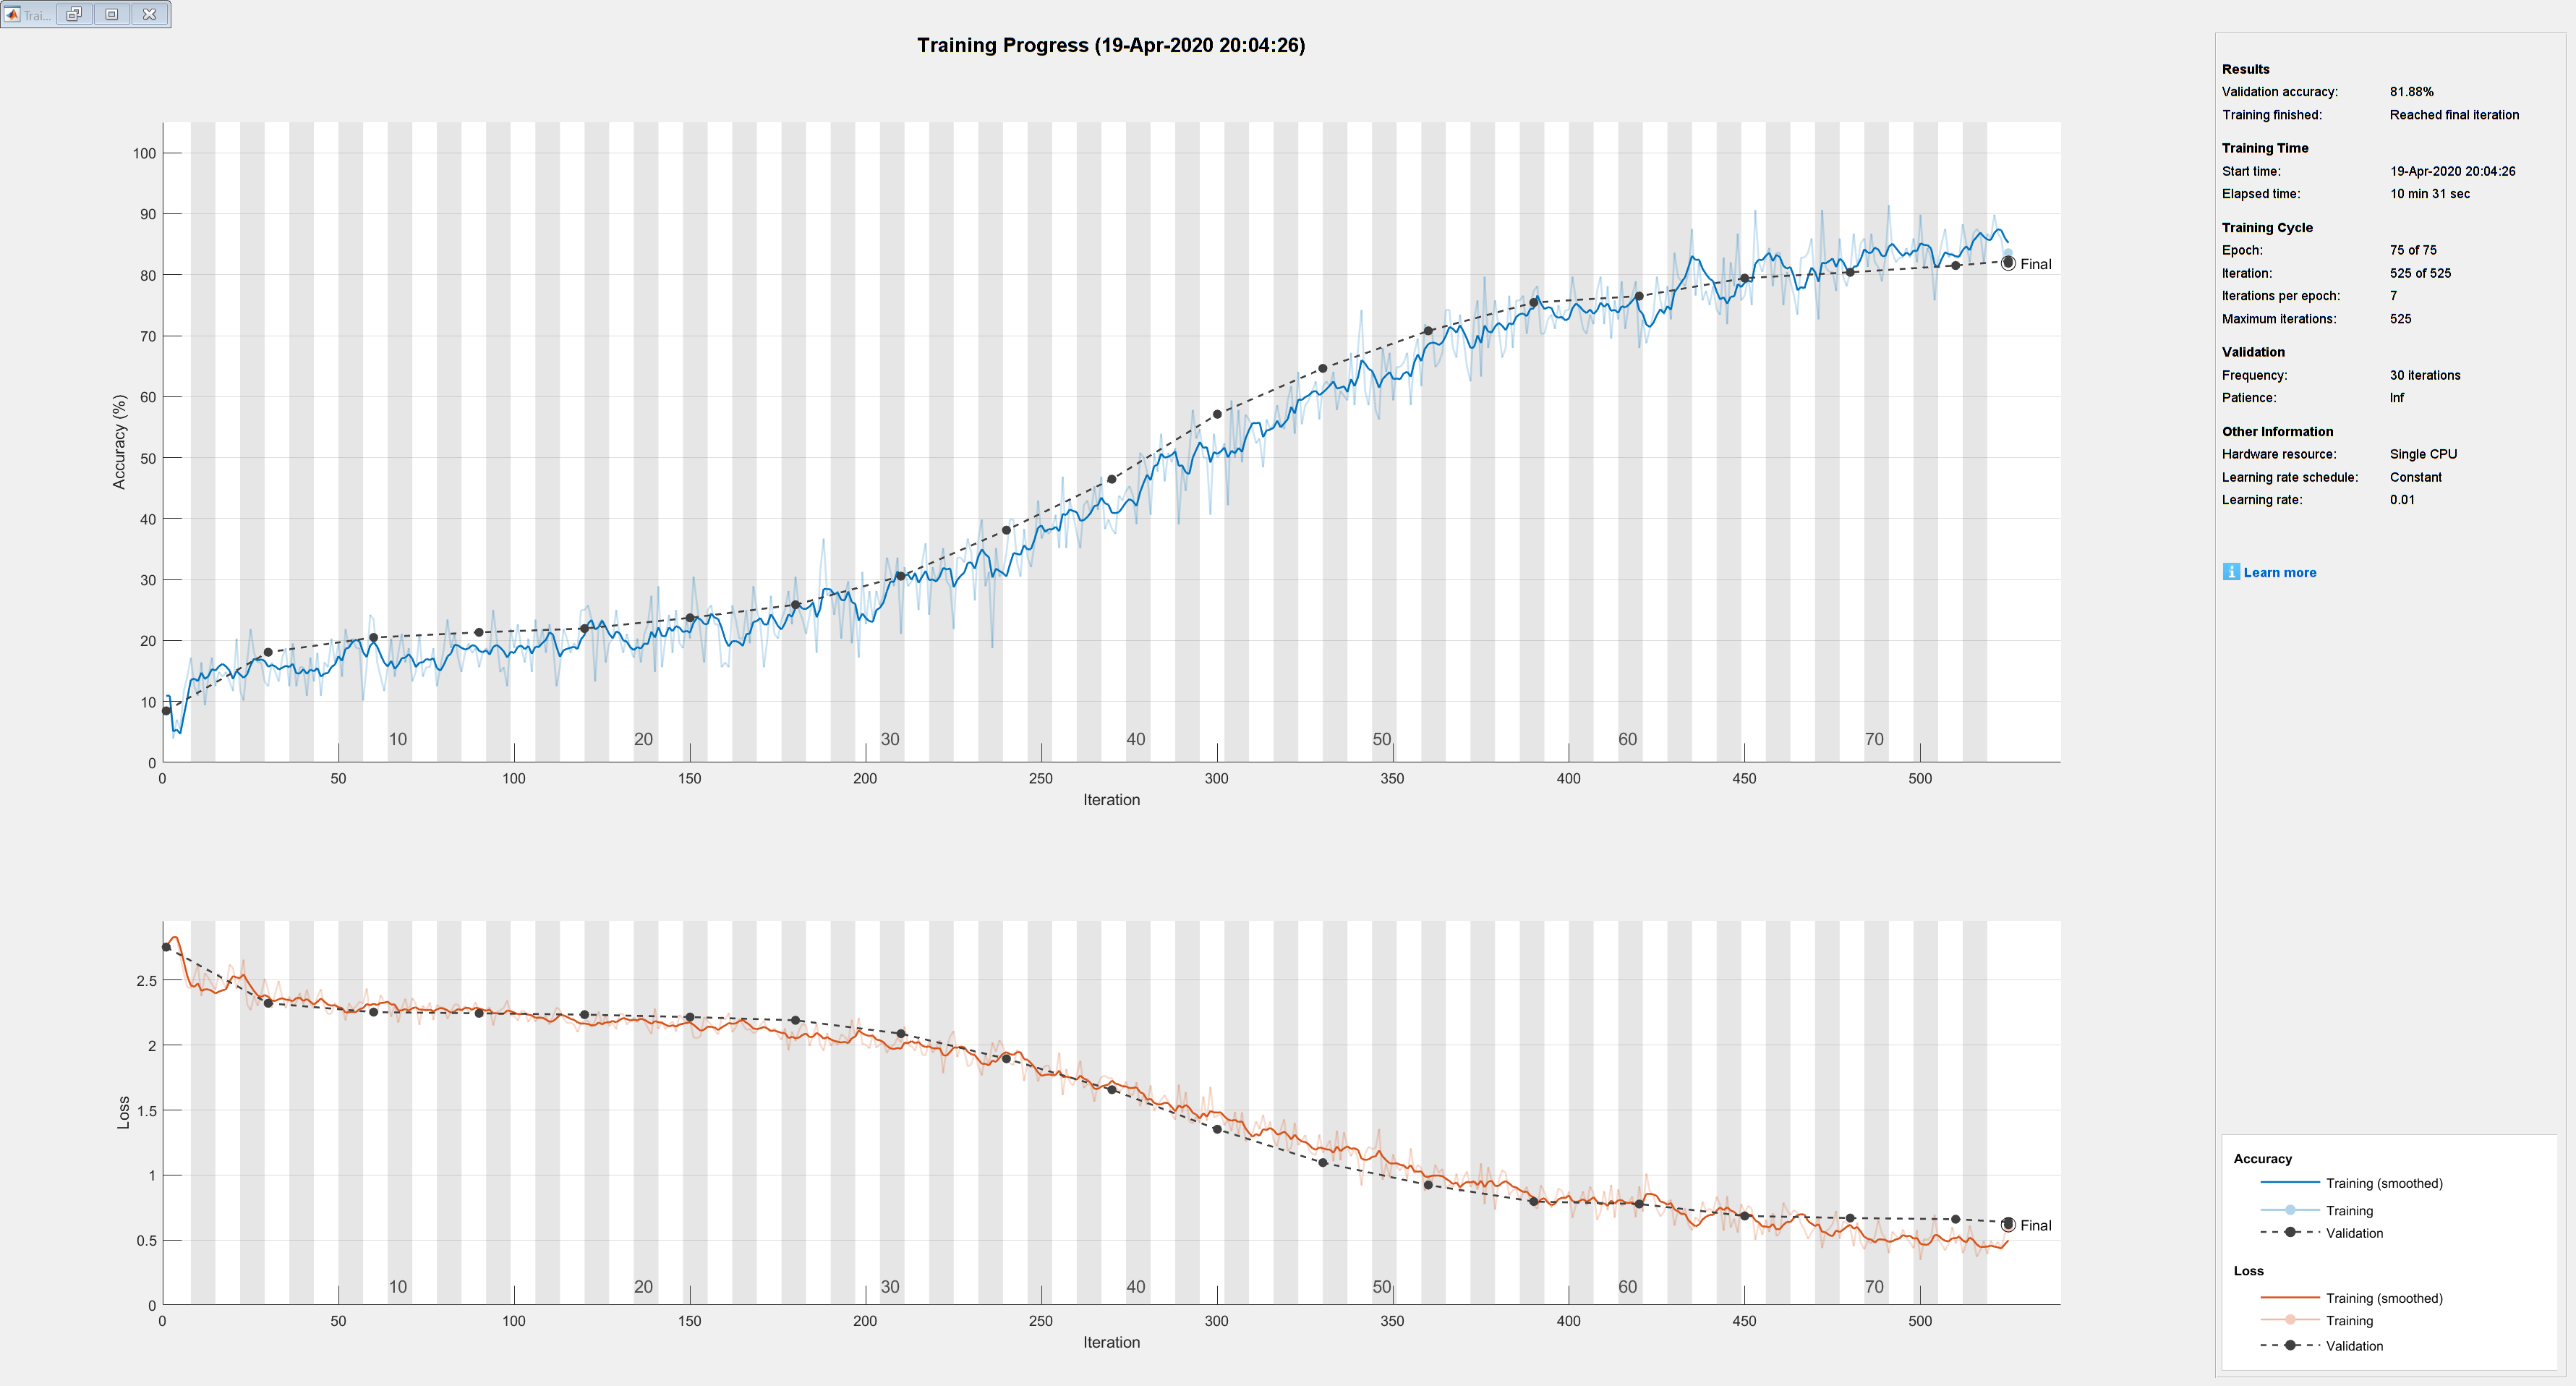

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',75, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{test, test_y}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
trainedNet = trainNetwork(augimdsTrain, layers, options);

YPred = classify(net,test);
YValidation = test_y;
figure
confusionchart(test_y, YPred)

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [10×10 double]
         ClassLabels: [10×1 categorical]

  Show all properties


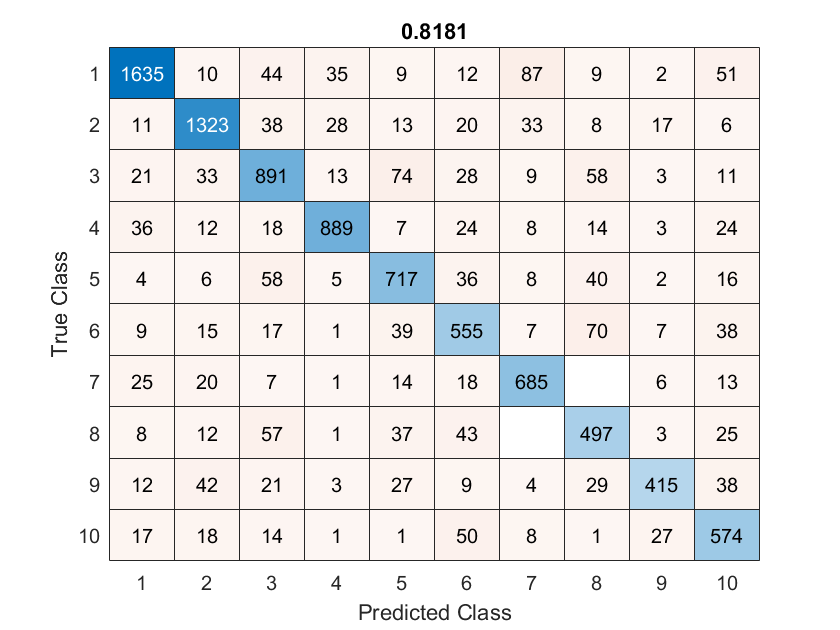

title(sum(YPred == YValidation)/numel(YValidation))

Fine tune an existing model

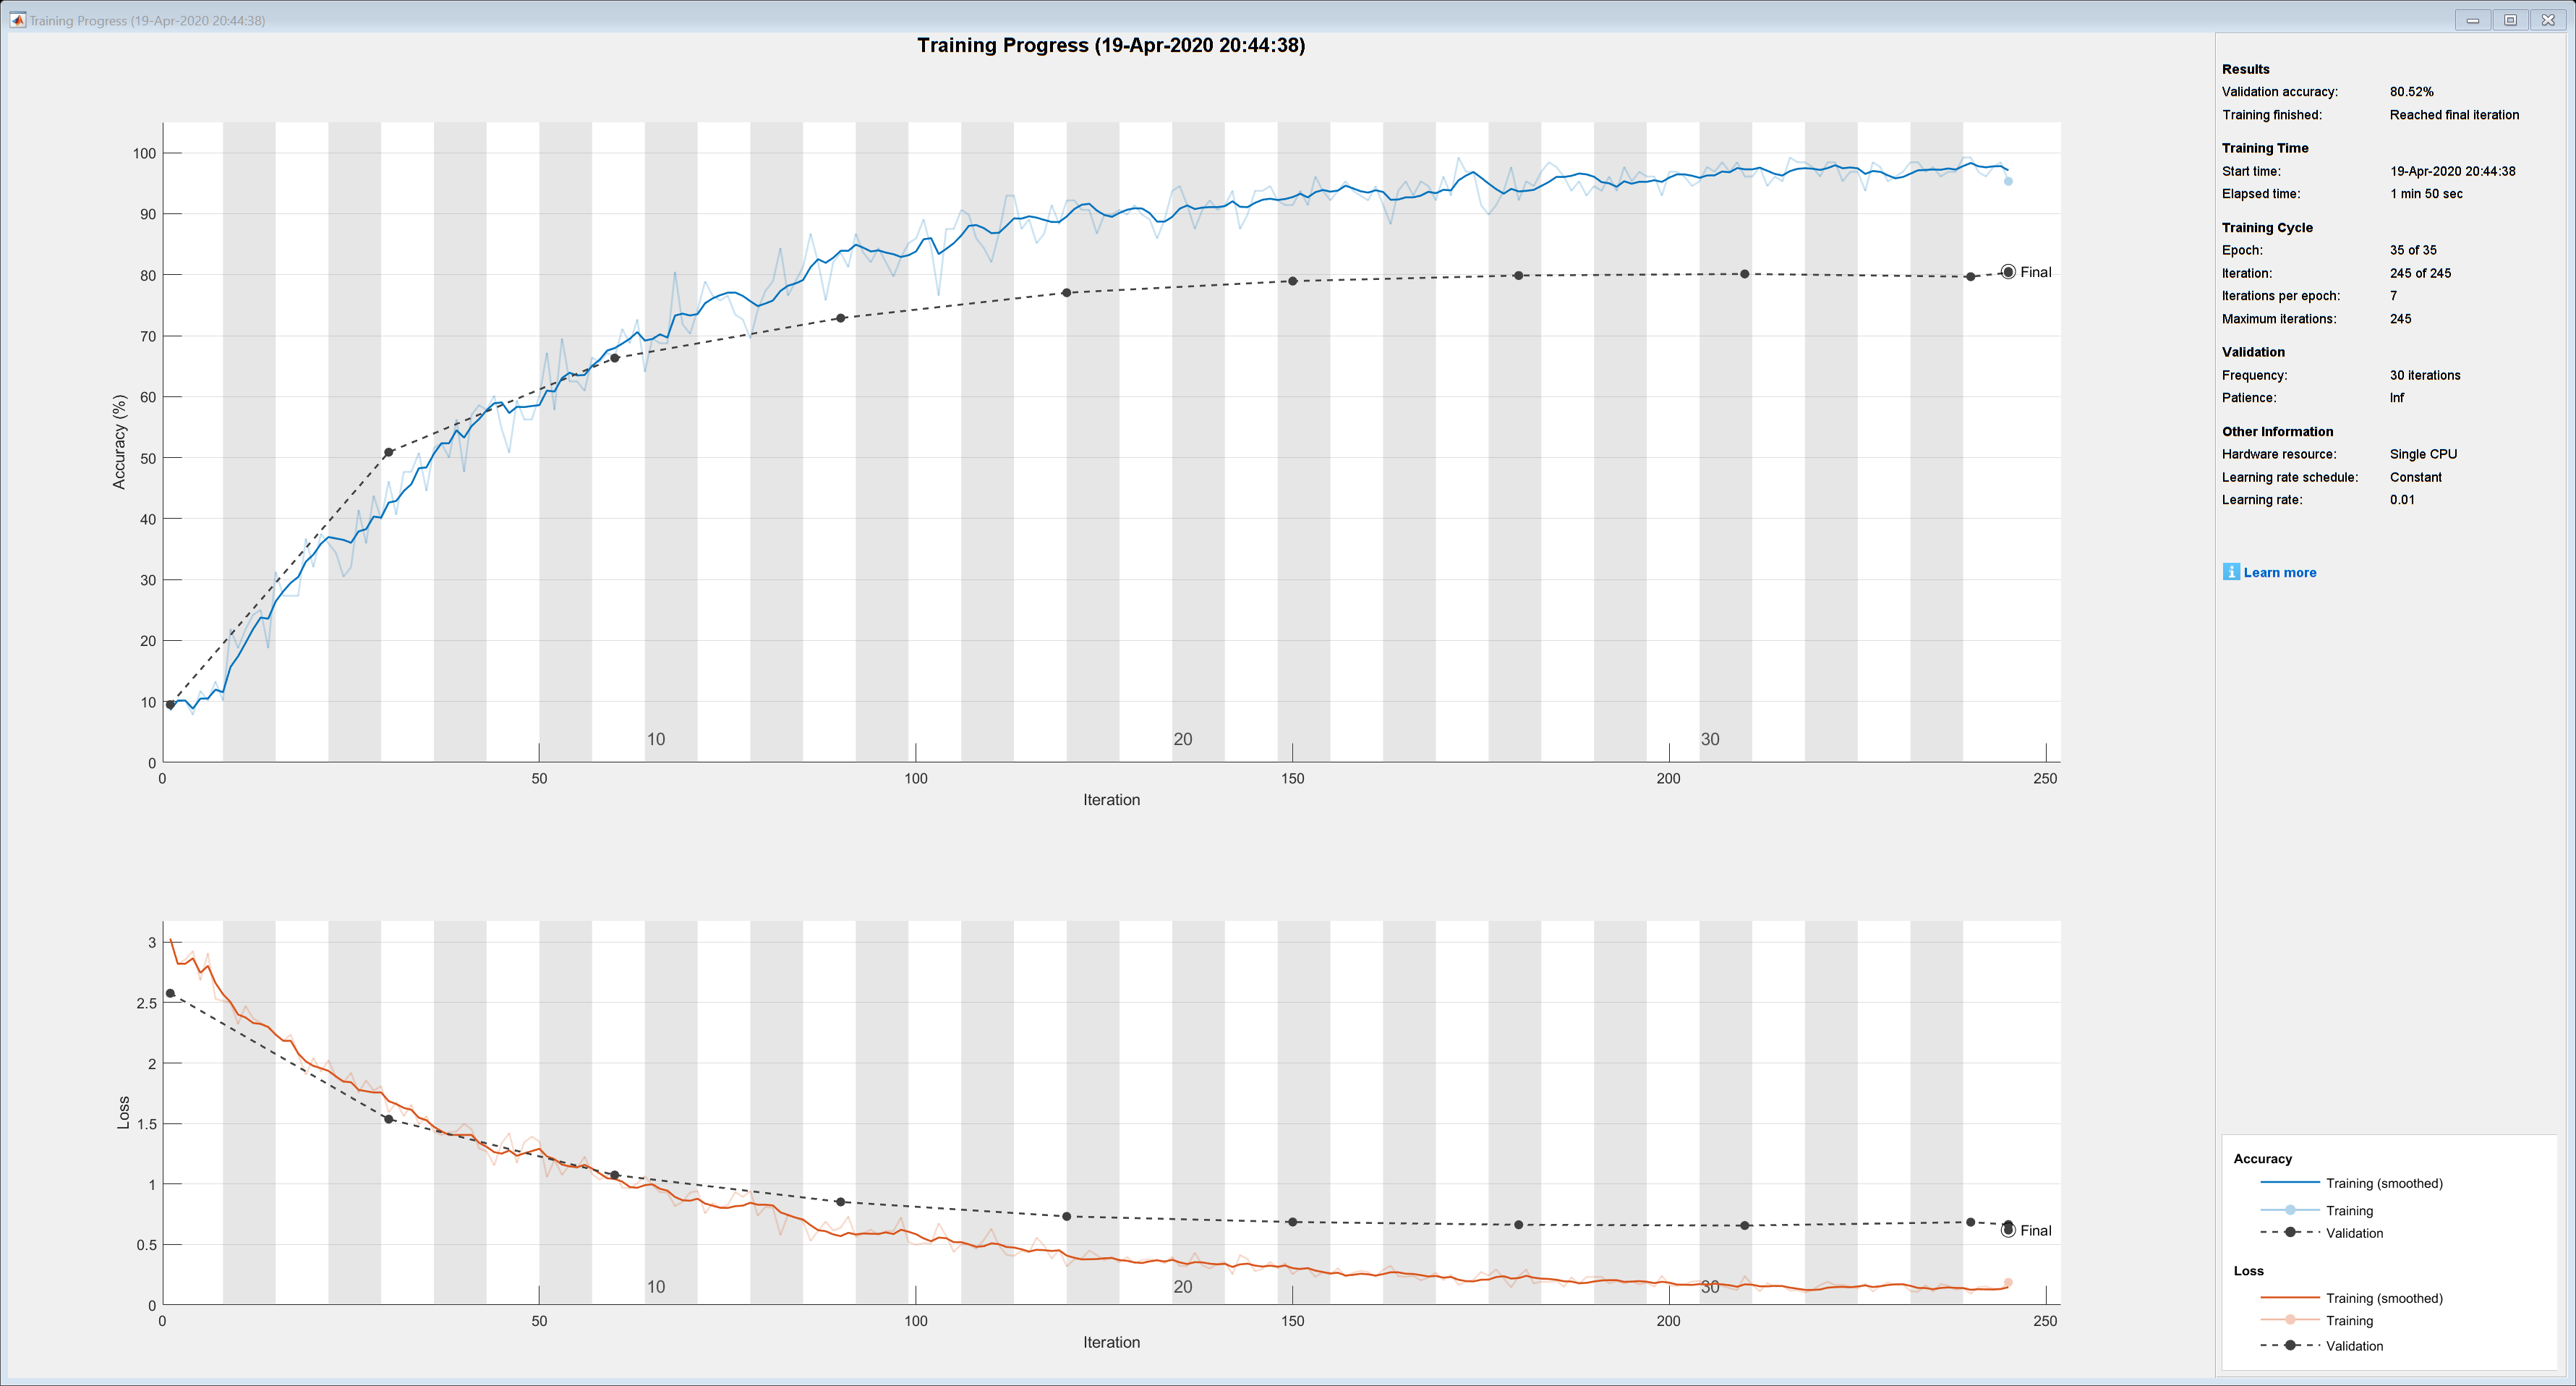

load('trained_vggs/vgg6-CIFAR10.mat')
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',35, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{test, test_y}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = removeLayers(net, {'fcFinal', 'softmax', 'classoutput'});
new_layers = [
    fullyConnectedLayer(10,'Name','fcFinal')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name','classoutput')];
net = addLayers(net, new_layers);
net = connectLayers(net, 'fcblock_2_DO', 'fcFinal');
transferedSVHN = trainNetwork(train, train_y, net, options);